# Illustrating equal irradiance for uniform fields when f/# is equal

In class I described why lenses with the same f/# produce an equal irradiance image at the sensor for images of uniform patches. 

The equality is not true for little patterns, such as images made of dots or lines. I show the calculations using ISETCam here, and explain how these observations are reconciled.

## Background

For uniform fields the picture and idea is shown in this comparison of two lenses with the same f/#.  The lens with the smaller aperture collects fewer rays from the top point of the arrow, compared to the lens with the larger aperture.  

However, the image from the larger diameter lens is magnified (larger).  The light collected is greater, but it is spread out over more of the image plane.  The magnification (spreading out of the image) counters the fact that more photons are gathered from a point. The two factors - light gathering and magnification - cancel each other out.  So for a uniform patch the two lenses produce the same irradiance.  

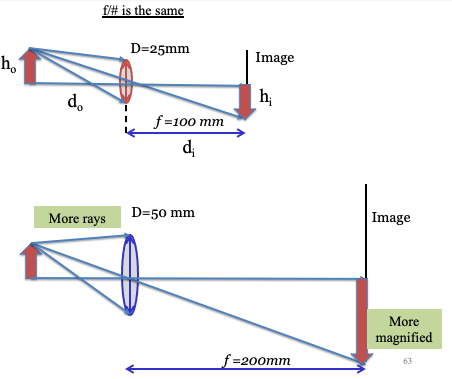

## Uniform scene

First, initialize ISETCam.

ieInit

Create a uniform scene.

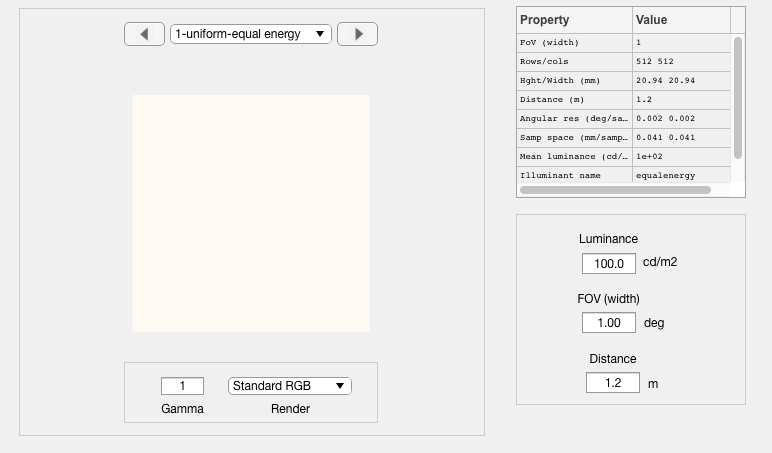

imSize = 512;
scene = sceneCreate('uniform ee',imSize);
scene = sceneSet(scene,'fov',1);
sceneWindow(scene);

Calculate the optical image using ideal lenses with two different focal lengths, but the same f/#.

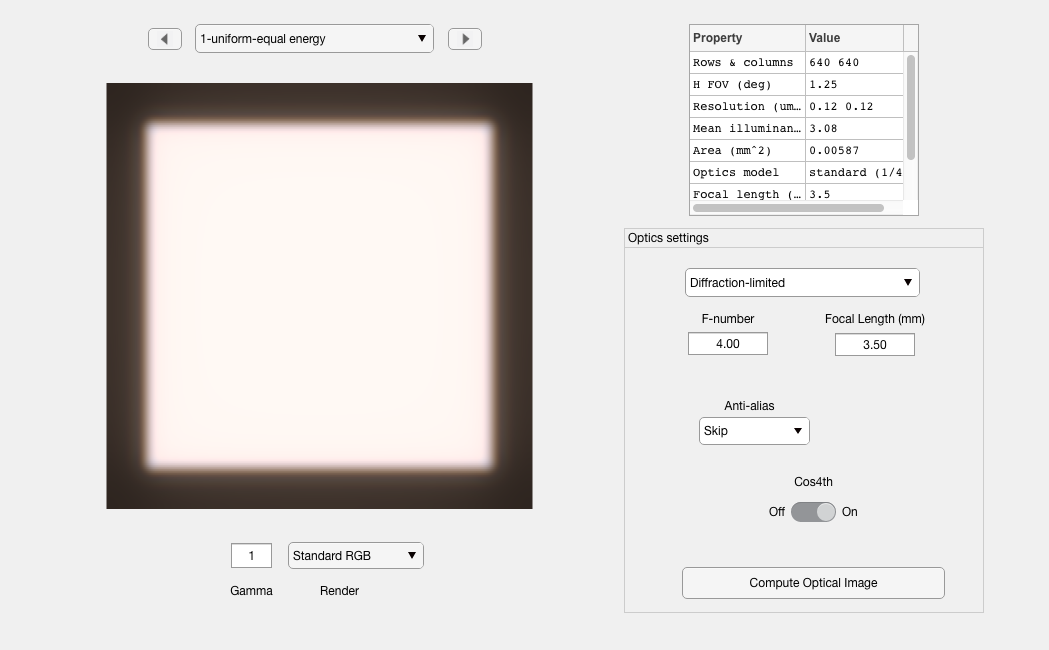

% One focal length
oi = oiCreate;
oi = oiSet(oi,'optics focal length',0.0035);

oi = oiCompute(oi,scene);
oiWindow(oi);

% Here is the mean illuminance of the optical image.  The illuminance is a
% weighted sum of the irradiances at different wavelengths.
fprintf('\nMean illuminance %f lux\n',oiGet(oi,'mean illuminance'))


Mean illuminance 3.075206


**Now double the focal length, leaving the f/# the same.**

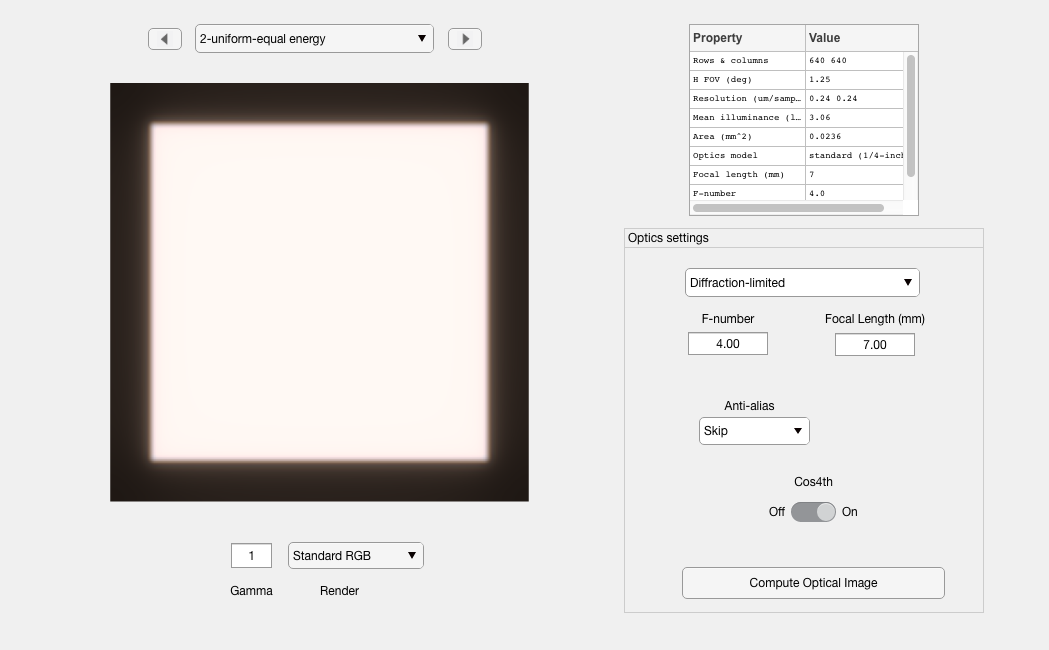

oi2 = oiSet(oi,'optics focal length',oiGet(oi,'optics focal length')*2);
oi2 = oiCompute(oi2,scene);
oiWindow(oi2);

fprintf('\nMean illuminance %f lux\n',oiGet(oi2,'mean illuminance'))


Mean illuminance 3.057511


The small difference is probably something to do with the edge.

### Single line comparison

Now, compare what happens when we create an image of a single line.  

The two lenses have the same f/#, and therefore they spread the light from the line over the same space - the linespread of two lenses is the same when the f/# is the same.  You will see this in the plots, although it may not be obvious from the images.  But notice:  The spatial resolution of the optical image differs when we change the focal length because the magnification is changed.

Here is a thin line

scene = sceneCreate('line',512);
scene = sceneSet(scene,'fov',1);

Here is the linespread with the short focal length oi

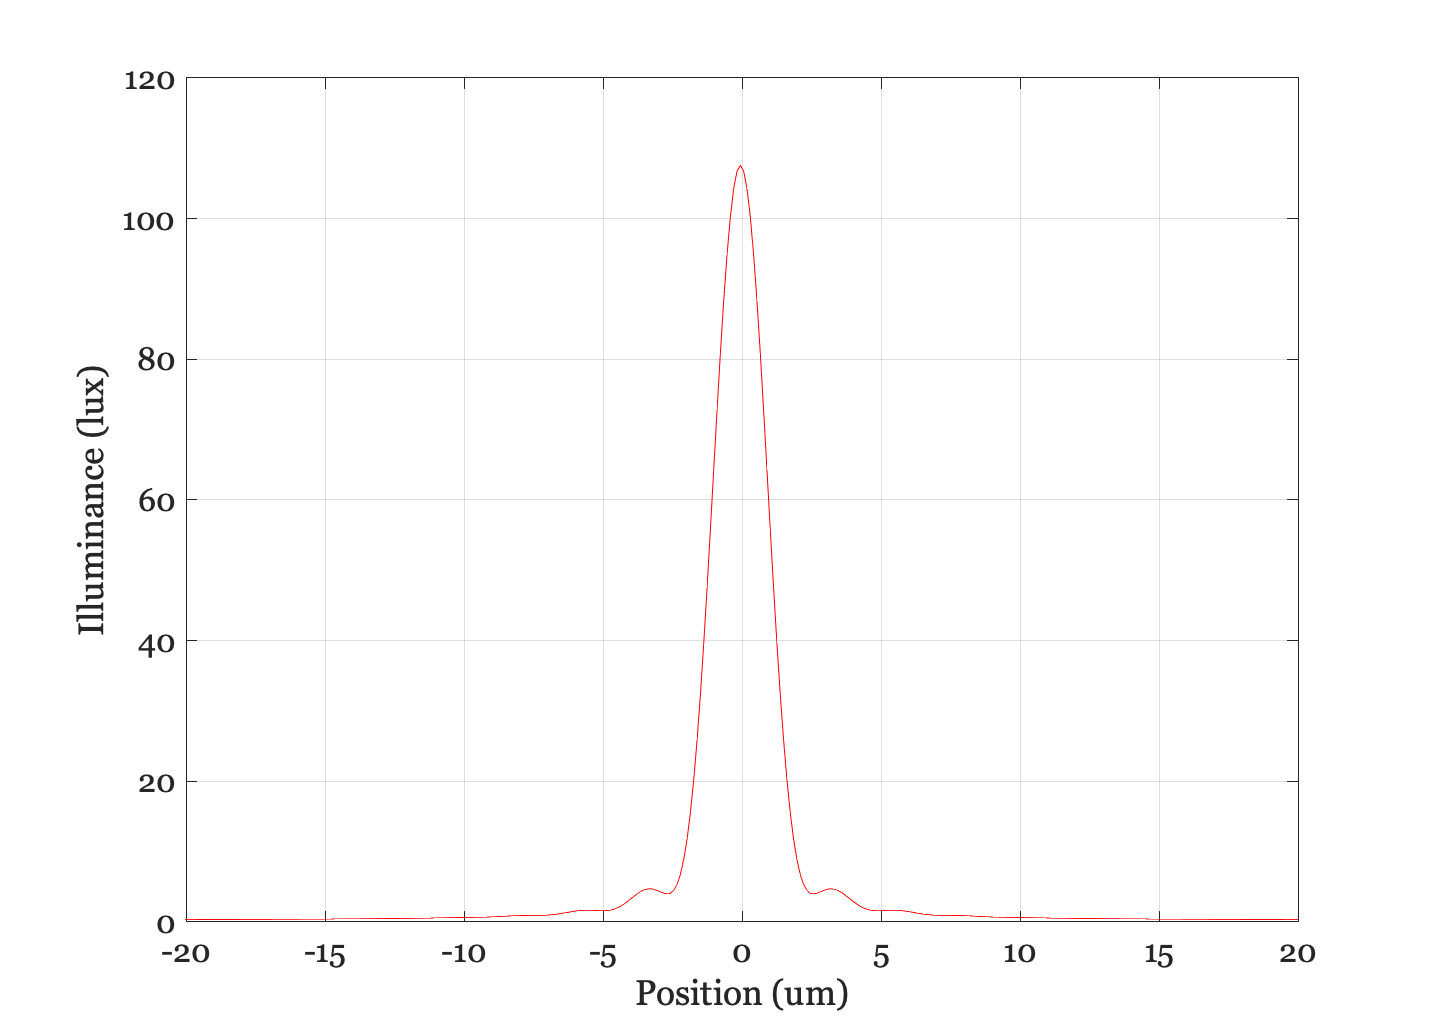

oi = oiCompute(oi,scene);
% oiWindow(oi);

data1 = oiPlot(oi,'illuminance hline',[1 256]);
set(gca,'xlim',[-20 20],'xtick',(-20:5:20))

% oiPlot(oi,'irradiance hline',[1 256],500);
% set(gca,'xlim',[-20 20],'xtick',[-20:5:20])

Now with the optics with double the focal length, but leave the f/# fixed.

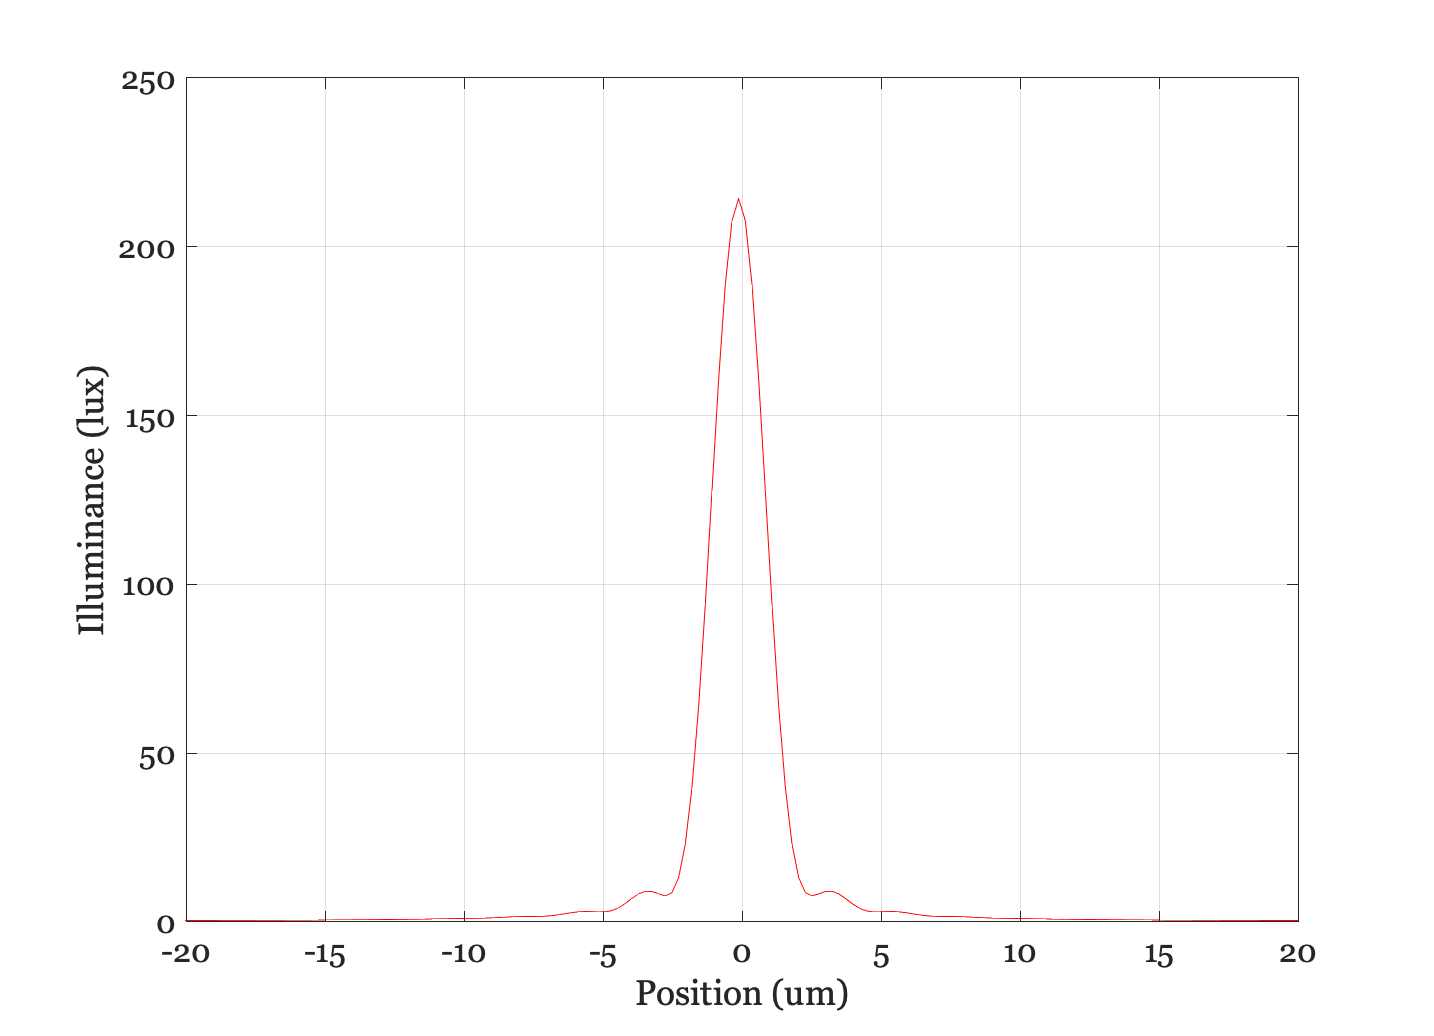

oi2 = oiCompute(oi2,scene);
data2 = oiPlot(oi2,'illuminance hline',[1 256]);
set(gca,'xlim',[-20 20],'xtick',(-20:5:20))

Here is an overlay of the two curves, showing that more rays get in from a single thin line.  

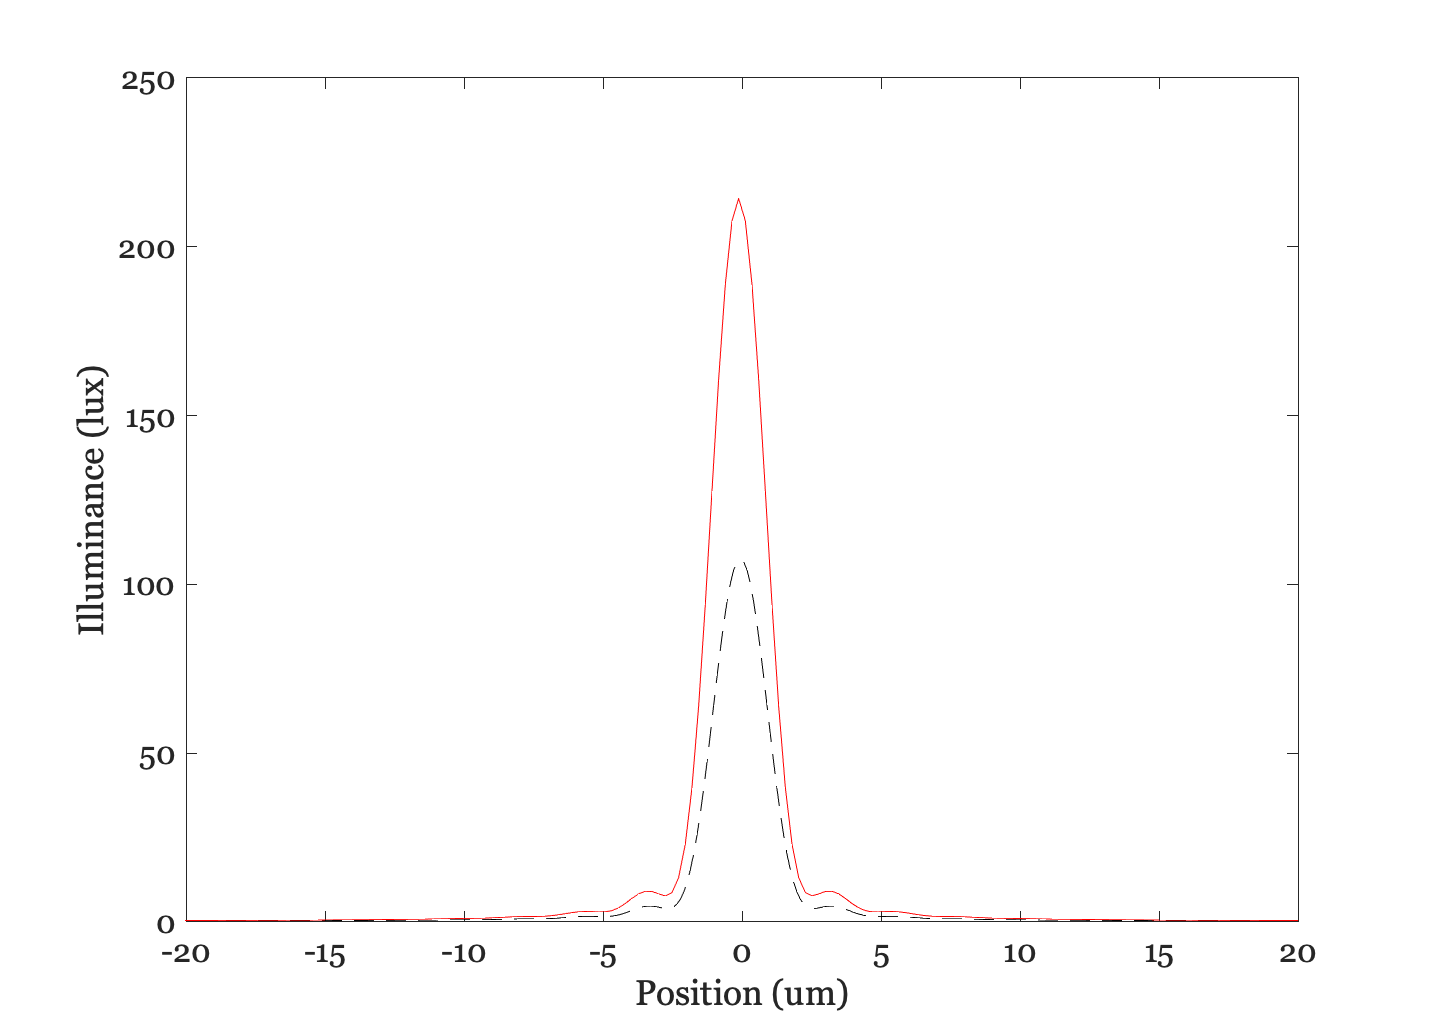

ieNewGraphWin;
plot(data1.pos,data1.data,'k--',data2.pos,data2.data,'r-');
set(gca,'xlim',[-20 20],'xtick',(-20:5:20));
xlabel('Position (um)'); ylabel('Illuminance (lux)');

The two lines spread by the same amount, because they are very thin lines imaged by ideal lenses with the same f/#.  But the line from the lens with the larger aperture has higher illuminance.  This seems to be the opposite of what we saw with the uniform field.  So, how do we explain this?  

### Magnification

The explanation is arises from considerieng the image magnification.  We can calculate the impact using a grid stimulus like this, where we control the separation between the grid lines.  Let's start with a grid where the lines are separated.

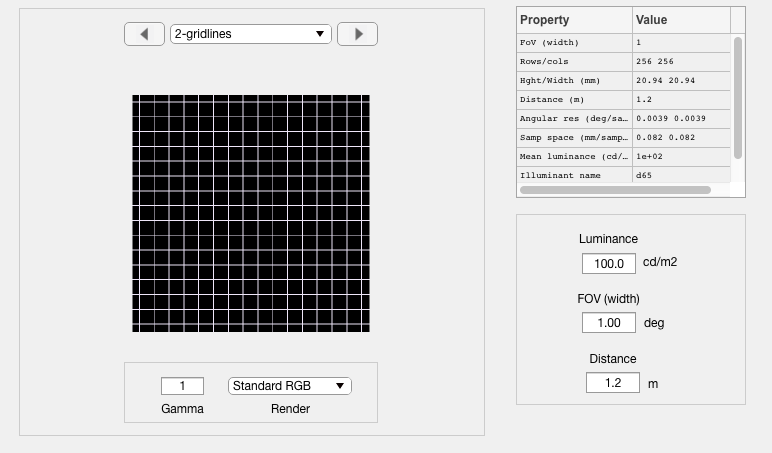

sep = 16;
scene = sceneCreate('grid lines',256,sep);
scene = sceneSet(scene,'fov',1);
sceneWindow(scene);

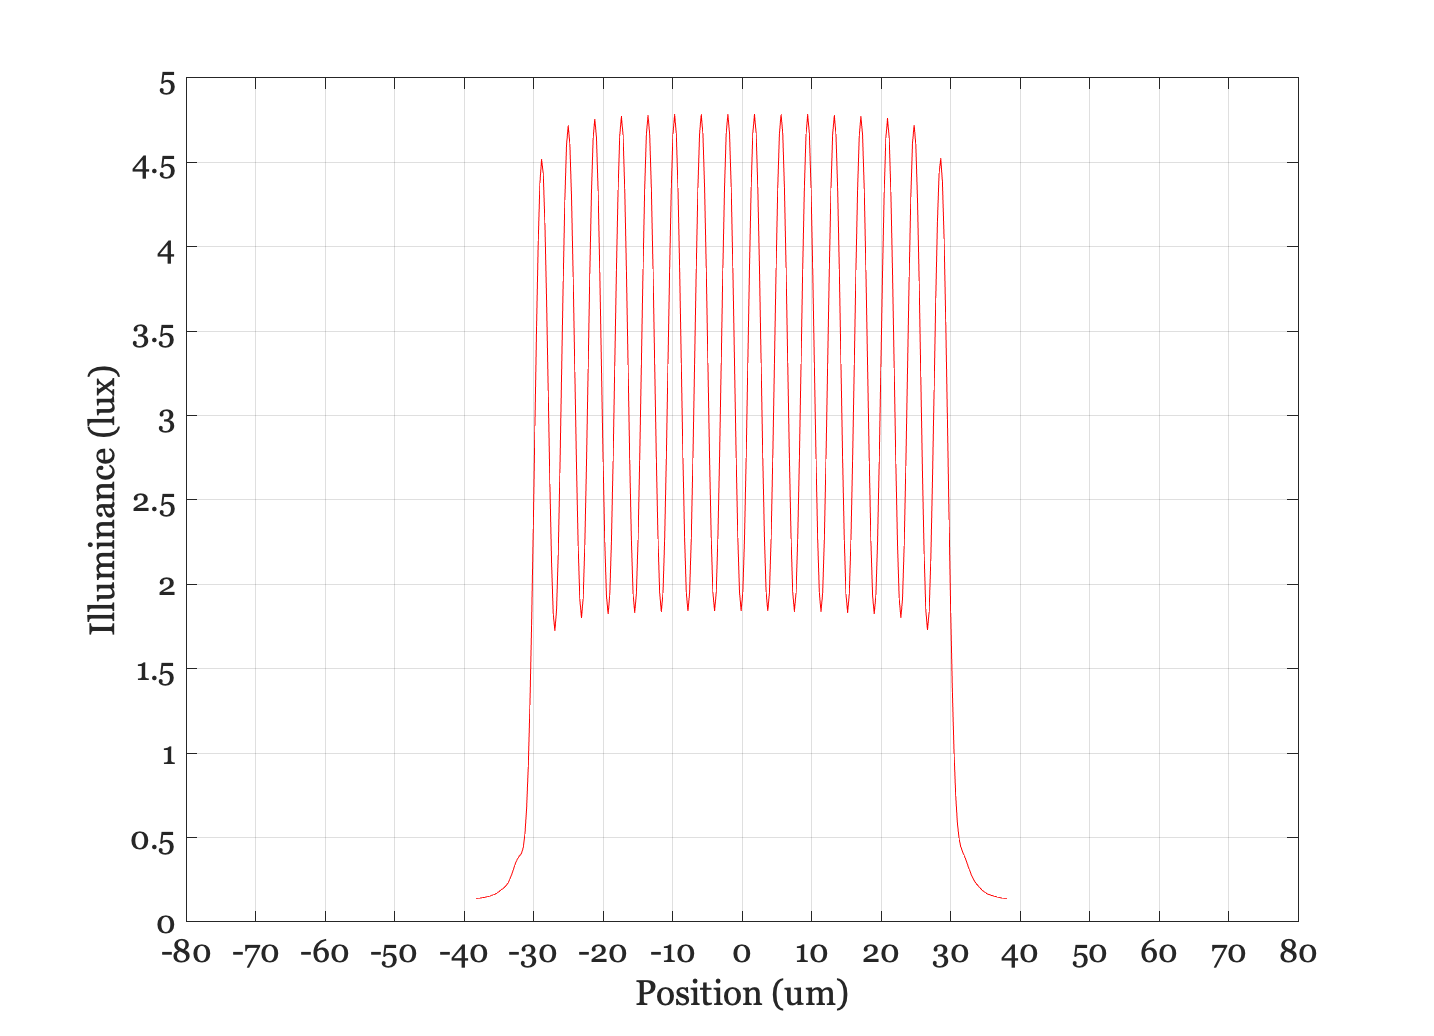

oi = oiCompute(oi,scene); % oiWindow(oi); 
data1 = oiPlot(oi,'illuminance hline',[1 256]);
set(gca,'xlim',[-80 80],'xtick',(-80:10:80));

The peaks are spaced about 5 $um$ apart, and highest level is a little below 5 lux and lowest level is about 2 lux.

The longer focal length has a different pattern.

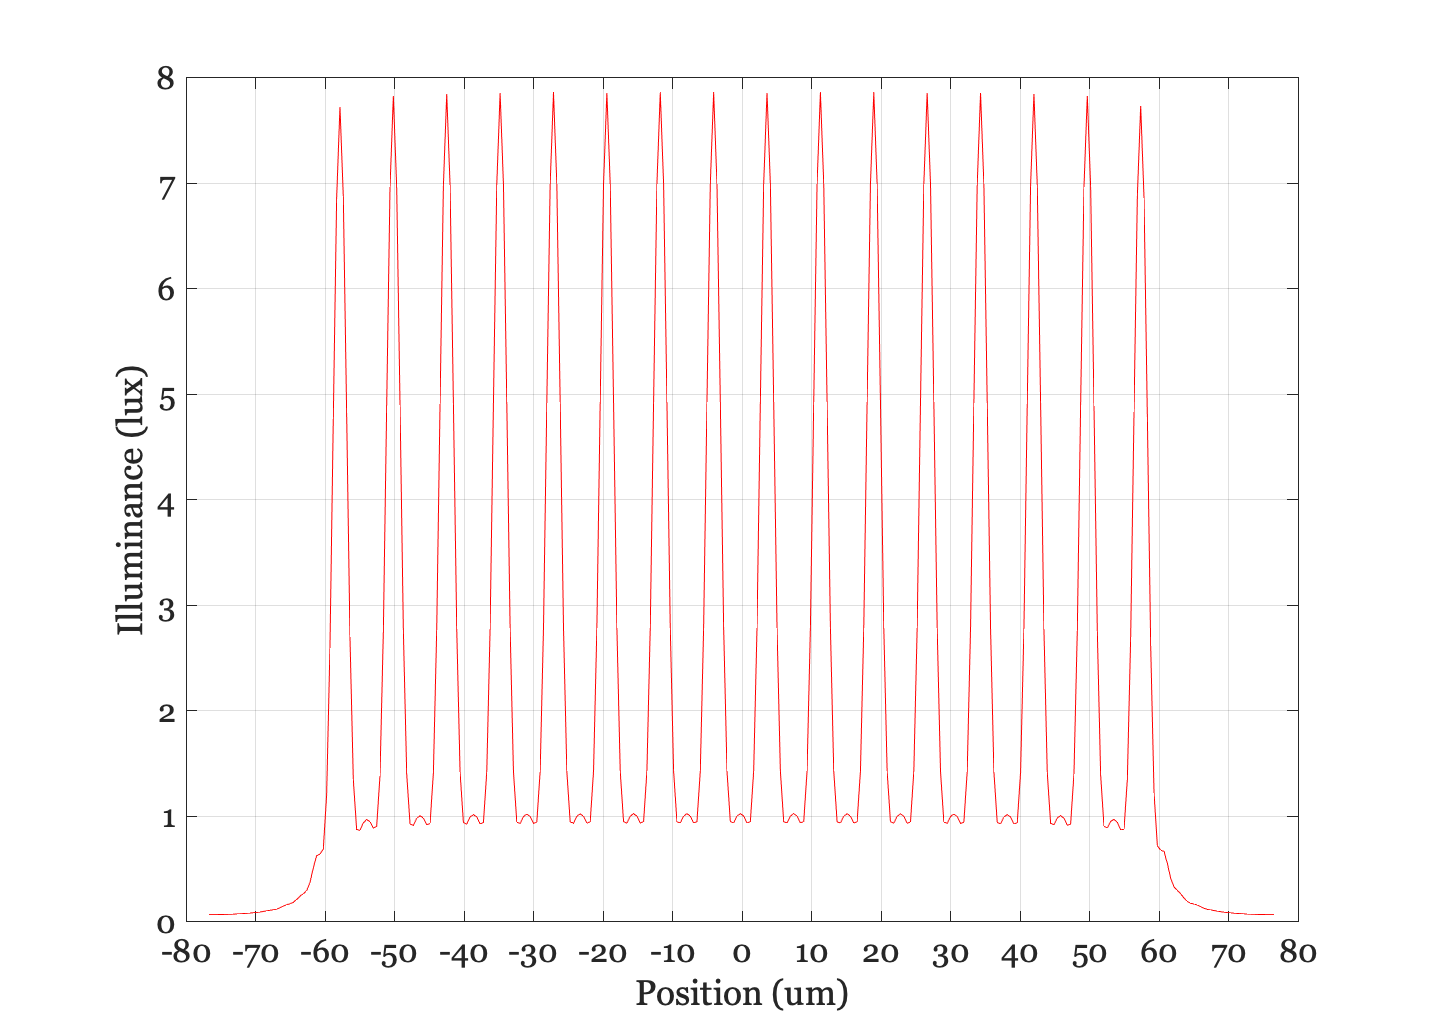

oi2 = oiCompute(oi2,scene);
oiPlot(oi2,'illuminance hline',[1 256]);
set(gca,'xlim',[-80 80],'xtick',(-80:10:80));

The peaks are spaced about 10 $um$ apart, and the highest level is nearly 8 lux and the lowest level about 1 lux.  

Let's repeat the calculation as we reduce the separation between the grid lines.  Remember: When there is no separation, we have a uniform field, of course.  

Even with a separation of 8, the lines from the short focal length merge together and appear to form a uniform irradiance image.  This merging happens to the longer focal length case with a separation of 4.  

In all these cases, the mean illuminance level is about the same because the magnification counteracts the higher illuminance.  For an explanation, return to the image at the top of the tutorial.

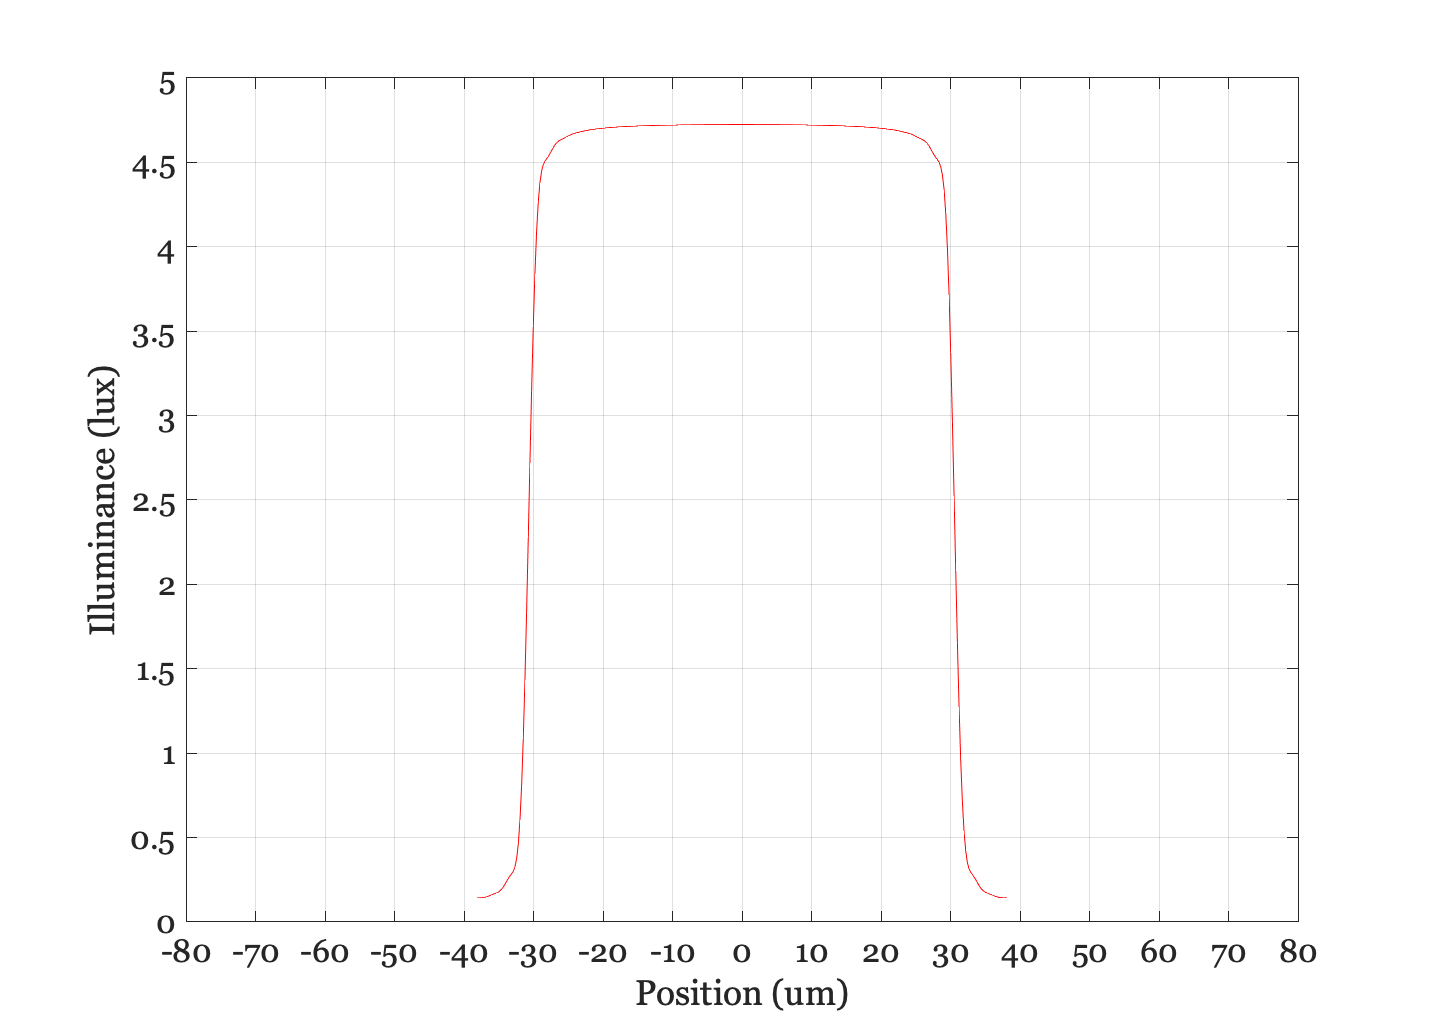

sep = 4;   % 8, 4, 2
scene = sceneCreate('grid lines',256,sep);
scene = sceneSet(scene,'fov',1);
oi = oiCompute(oi,scene);
oi2 = oiCompute(oi2,scene);
ieNewGraphWin;
data = oiPlot(oi,'illuminance hline',[1 256]);
set(gca,'xlim',[-80 80],'xtick',(-80:10:80));

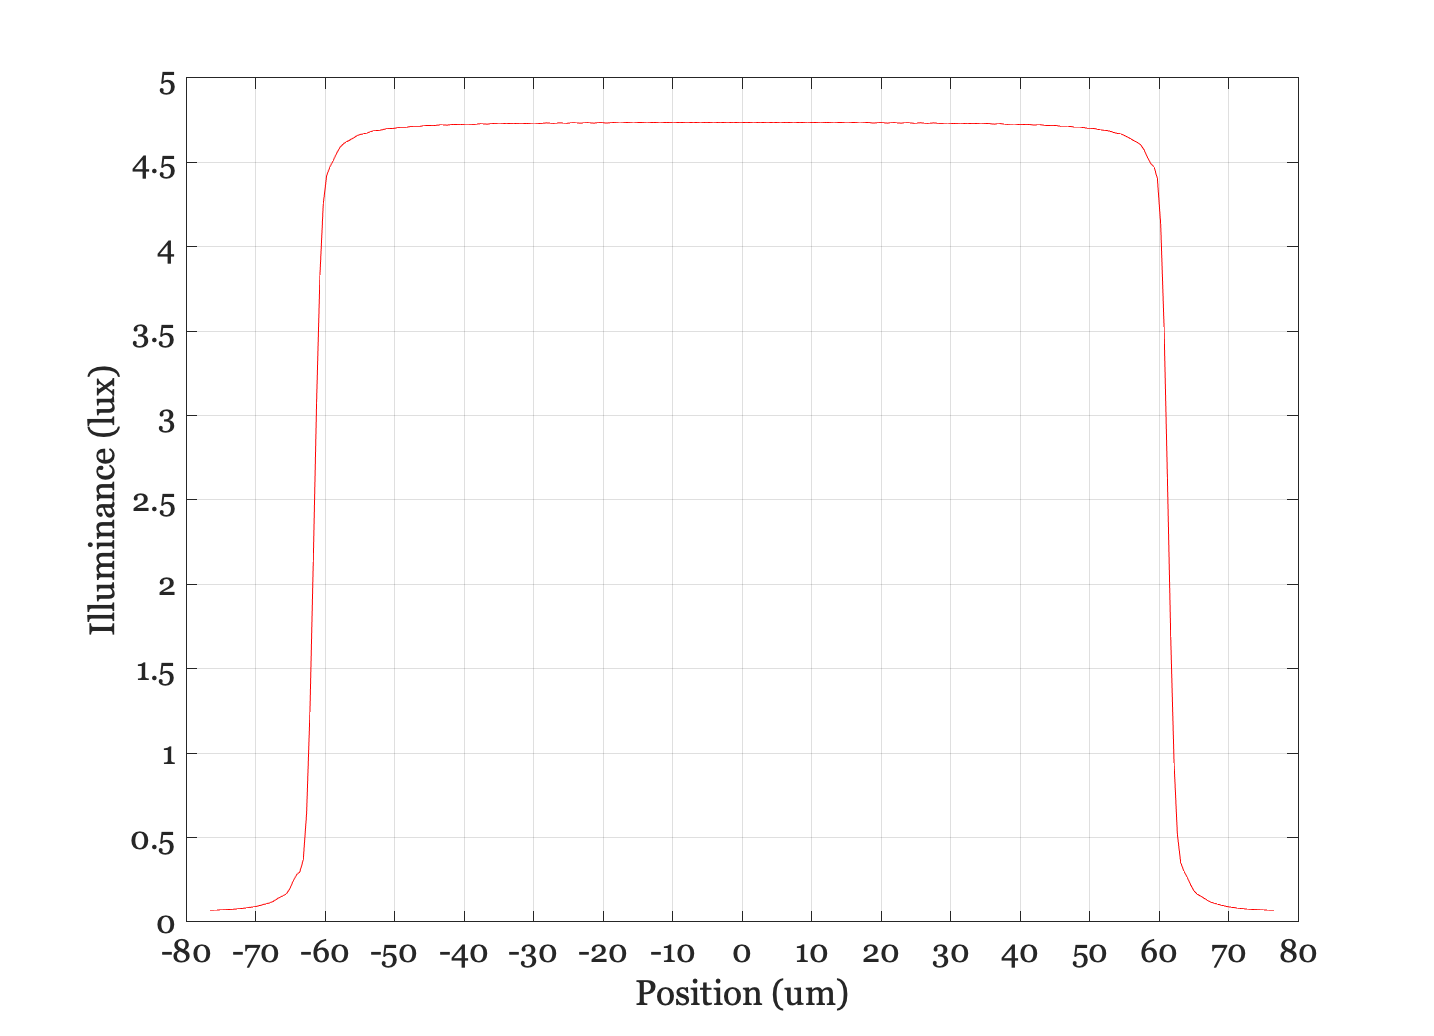

data2 = oiPlot(oi2,'illuminance hline',[1 256]);
set(gca,'xlim',[-80 80],'xtick',(-80:10:80));